# MPC II

## Exercise 3.3

The water temperature in a heated swimming pool, $\theta$, is related to the heater input power, $q$, and the ambient air temperature, $\theta_a$, according to the equation 


$$T\frac{\;d\;\theta }{d\;t}=k\;q+\theta_a -\theta$$


where $T=1$ hour and $k=0\ldotp 2\;\degree \frac{C}{\mathrm{kW}}$. (It is assumed that the water is perfectly mixed, so that it has the uniform temperature.) Predictive control is to be applied to keep the water at a desired temperature, and a sampling interval $T_s =0\ldotp 25$ hour is to be used. The control update interval is to be the same as $T_s$. 

### (a) Use MATLAB's control system toolbox to show that the corresponding discrete-time model is: $\theta \left(k+1\right)=0\ldotp 7788\theta \left(k\right)+0\ldotp 0442q\left(k\right)+0\ldotp 2212\theta_a \left(k\right)$Form the corresponding model in the Model Predictive Control Toolbox's 'MOD' format, assuming that $q$ is the control input and that $\theta_a$ is an unmeasured disturbance. 

We have the system 


$$T\frac{\;d\;\theta }{d\;t}=k\;q+\theta_a -\theta$$


Which we can write in the form:


$$T\dot{\theta} =k\;q+\theta_a -\theta$$
 
$$\to \dot{\theta} =-\frac{1}{T}\theta +\left\lbrack \begin{array}{cc}
\frac{k}{T} & \frac{1}{T}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
q\\
\theta_a 
\end{array}\right\rbrack$$


So now we have:


$$A=-\frac{1}{T}$$



$$B=\left\lbrack \begin{array}{cc}
\frac{k}{T} & \frac{1}{T}
\end{array}\right\rbrack$$


So now i can set up the state space model:

T = 1; % Hour
Ts = 0.25; % Hour
k = 0.2; % C/kW

A = -1/T;
B = [k/T 1/T];
C = 1;
D = 0;

css_model = ss(A,B,C,D);

Now i should convert it to discrete time:

dss_model = c2d(css_model,Ts)

dss_model =
 
  A = 
           x1
   x1  0.7788
 
  B = 
            u1       u2
   x1  0.04424   0.2212
 
  C = 
       x1
   y1   1
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.
Mod

So now i have the model on the desired format. Then i need to find the corresponding model in the MPC toolbox. 

We need to specify the model info in the format specified in the format stated in the ss2mod help. 

minfo = [Ts, 1,1,0,1,1,0]

minfo =     0.2500    1.0000    1.0000         0    1.0000    1.0000         0


mpc_model = ss2mod(dss_model.A, dss_model.B, dss_model.C, dss_model.D,minfo)

mpc_model =     0.2500    1.0000    1.0000         0    1.0000    1.0000         0
       NaN    0.7788    0.0442    0.2212         0         0         0
         0    1.0000         0         0         0         0         0


### (b) Verify that if the weights $Q=1$ and $R=0$, and the horizons $H_p =10$ and $H_u =3$ (and $H_w =1$) are used, then $K_s =K_{\mathrm{MPC}} \left\lbrack \begin{array}{ccc}
1 & -\Psi  & -\Gamma 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
22\ldotp 604 & -17\ldotp 504 & -22\ldotp 604
\end{array}\right\rbrack$ Where $K_s$ is the unconstrained controller gain matrix Ks produced by the Model Predictive Control Toolbox smpccon, and that stable closed-loop behavior is obtained. 

First defining the Horizons:

Hp = 10;
Hu = 3;
Hw = 1;

And the weights:

Q = 1;
R = 0;

So now we can use this function to compute the gain matrix $K_s$

Ks = smpccon(mpc_model,Q,R,10,Hp)

Ks =    22.6041  -17.6041  -22.6041


And this is indeed the specified Gain matrix as illustrated in the exercise.

So now i need to verify if stable closed-loop control behavior is obtained. 

To do this i can use 

closed_loop_system = smpccl(mpc_model,mpc_model,Ks)

closed_loop_system =     0.2500    4.0000    4.0000         0         0    3.0000         0         0         0
       NaN   -0.2212   -0.7788         0    0.0442    1.0000   -1.0000    0.0442    0.2212
         0   -1.0000    0.0000         0         0    1.0000   -1.0000         0         0
         0    0.0000    0.0000         0         0    1.0000    0.0000         0         0
         0  -22.6041  -17.6041         0    1.0000   22.6041  -22.6041         0         0
         0    1.0000         0         0         0         0         0         0         0
         0  -22.6041  -17.6041         0    1.0000   22.6041  -22.6041         0         0
         0    1.0000         0         0         0         0    1.0000         0         0


To check for stability i can verify that the eigenvalues of the system matrix of the closed loop system has all negative real parts. 

smpcpole(closed_loop_system)

ans =    0.0000 + 0.0000i
   0.7788 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i


As we can see, the system is not stable, because we have a positive real value in the second eigenvalue. 

### (c) If the air temperature $\theta_a$ is constant at $15\;\degree C$ verify that a set-piont for $\theta$ of $20\;\degree C$ is attained without error. Verify that this remains the case even if the pool parameters change to $T=1\ldotp 25$ hour, $k=0\ldotp 3\;\frac{\degree C}{\mathrm{kW}}$ but the predictive controlelrs internal model remains unchanged. 

First we have given the new parameters, and thus we need to recompute the model.

T = 1.25; % New Hour
Ts = 0.25; % Unchaged Hour
k = 0.3; % New C/kW

A = -1/T;
B = [k/T 1/T];
C = 1;
D = 0;

css_model_new = ss(A,B,C,D);
dss_model_new = c2d(css_model_new,Ts);
mpc_model_new = ss2mod(dss_model_new.A, dss_model_new.B, dss_model_new.C, dss_model_new.D,minfo)

mpc_model_new =     0.2500    1.0000    1.0000         0    1.0000    1.0000         0
       NaN    0.8187    0.0544    0.1813         0         0         0
         0    1.0000         0         0         0         0         0


So we have a new 

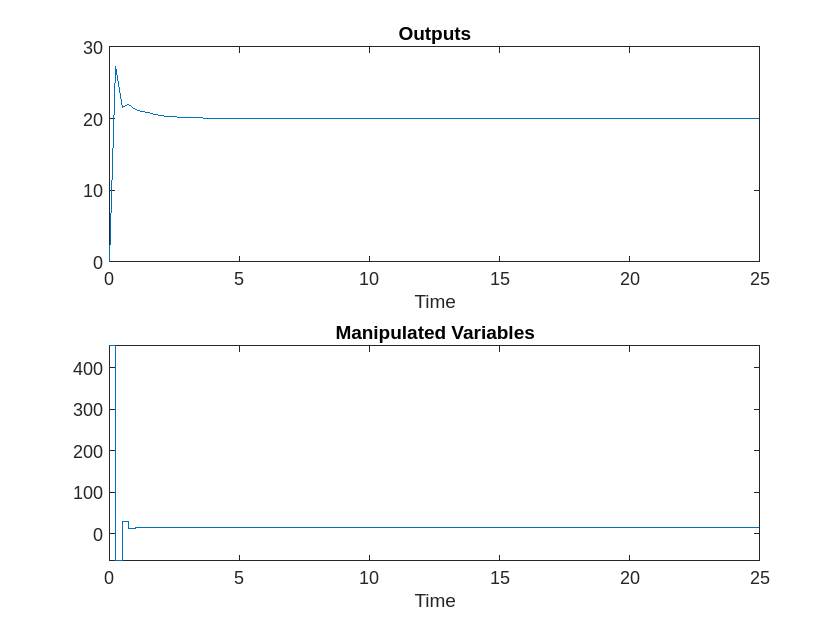

tend = 25; % Duration of the simulation
setpoint = 20; % The steady state attained without error.
airtemp = 15;
[wtemp,power] = smpcsim(mpc_model_new,mpc_model,Ks,tend,setpoint,[],[],[],[],airtemp,[]);
timevector = (0:0.25:120)'; % for plotting purposes
figure
plotall(wtemp,power,timevector(1:length(wtemp))) % Plot results

As we can see, the steady state error becomes 0, and the setpoint of $20\;\degree C$ is reached. 

### (d) Suppose that the air temperature follows a sinusoidal diurnal variation with amplitude $10\;\degree C$$\theta_a \left(t\right)=15+10\;\sin \left(\frac{2\pi }{24}t\right)$ Where $t$ is measured in hours. Verify that in the steady state, the mean water temperature reached the set-point exactly, but that $\theta$ has a small residual oscillation of amplitude approximately $0\ldotp 5\;\degree C$

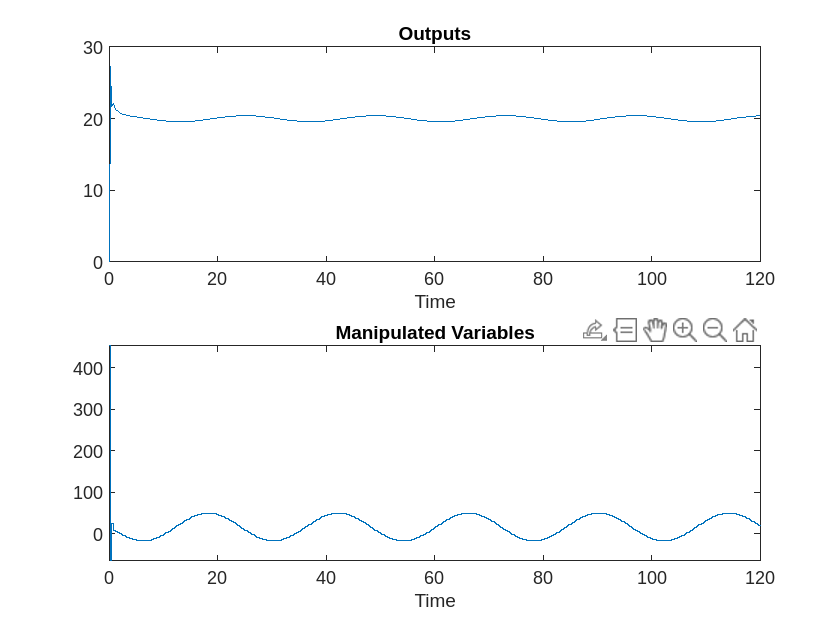

airtemp = 15+10*sin(2*pi*timevector/24); % Diurnal variation
tend = 120;
[wtemp,power] = smpcsim(mpc_model_new,mpc_model,Ks,tend,setpoint,[],[],[],[],airtemp,[]);
figure
plotall(wtemp,power,timevector)

As we can see on the figure, there is indeed a small fluctuation of the output of $0\ldotp 5\degree C$.

### (e) Now suppose that the input power is constrained: $0\le q\le 40\;\mathrm{kW}$ And the air temperature varies sinusoidally, as above. Investigate the behaviour of the predictive controlsystem - use Model Predictive Control Toolbox function scmpc.

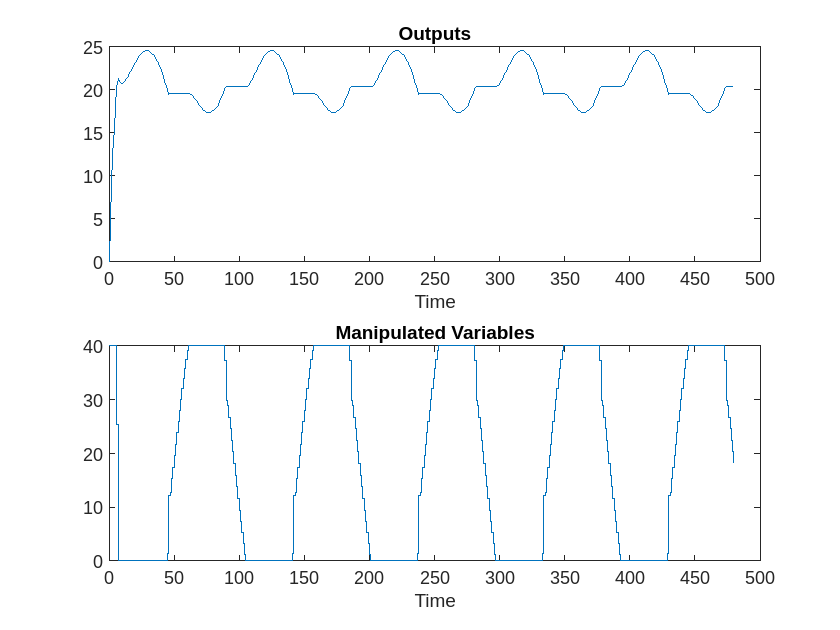

ulim = [ 0, 40, 1e6]; % Finite limit on slew rate required.
ywt = Q;
uwt = R;
M = 10;
P = Hp;

[wtemp,power] = scmpc(mpc_model_new,mpc_model,ywt,uwt,M,P,tend,setpoint,ulim,[],[],[],[],airtemp,[]);
figure
plotall(wtemp,power)